# Country Patterns 2015

Elaborated by Natanael Bolson

Supervised by Prof. Tad Patzek and Maxim Yutkin

EGG-ANPERC-KAUST 12/2020

Description: Apply filters to find a selected country and indentify  other countries with similar characteristics for the year 2015

clc
clear
close all

% Select the year from 1990 to 2015
Year_T=2015;
% Here Run the algorithm that makes the cateogrical classification
run Categorize.m
Pop=Data_EIA_H.Population(:,yo);
Pop(Clean)=[];
% to Print
P='F'; % 'T' prints

## China

CH=intersect(Wat_H,intersect(GDP_M,intersect(CO2_L,intersect(Land_L,intersect(Mat_L,find(Exp_cat(:,yo)~='L'))))))

CH =     22
    36
    95


Labels(CH)

ans = 3×1 cell array
    {'Botswana'}
    {'China'   }
    {'Malaysia'}


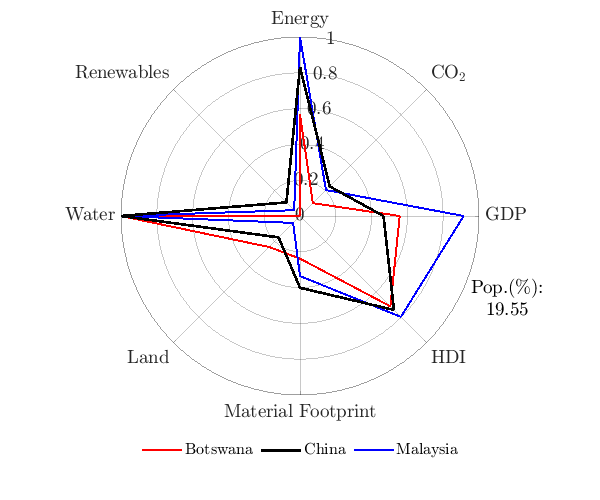

N=length(CH); 
C = hsv(N);
i=0;
figure()

for n=CH'
    i=i+1;
    if n==36
       Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color','k','linewidth',2)
    hold on 
    else
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
    end
end
 Values=Ind_S(36,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color','k','linewidth',2)
LegT=Labels(CH);
ax = gca;
axPos = ax.Position;
ax.Position = axPos+ [0 0.05 0 0];

legend(LegT,'Position',[0.45 0.05 0.1 0.1],'FontSize', 12,'NumColumns',3,...
    'box','off','interpreter','latex')
set(gcf,'Position',[0 0 600 500])
Pop_C=nansum(Pop(setdiff(CH,1)))/Pop(1)*100;
SP=sprintf('%.2f',Pop_C);
annotation('textbox', [0.845 0.45 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");
if P=='T'
    print('-depsc2','-r400','CH_15.eps')
end

## Russia

RU=intersect(En_H,intersect(Land_H,intersect(Wat_H,intersect(CO2_L,find(Ren_cat(:,yo)~='H')))));
Labels(RU)

ans = 4×1 cell array
    {'Australia' }
    {'Canada'    }
    {'Kazakhstan'}
    {'Russia'    }


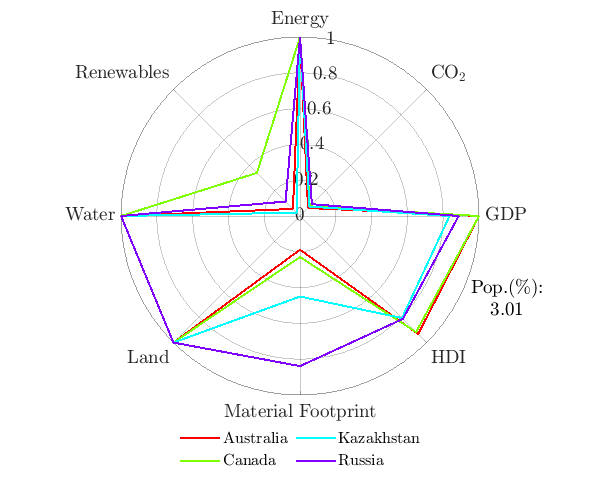

N=length(RU); 
C = hsv(N);
i=0;
figure()

for n=RU'
    i=i+1;
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

end

LegT=Labels(RU);
ax = gca;
axPos = ax.Position;
ax.Position = axPos+ [0 0.05 0 0];
legend(LegT,'Position',[0.45 0.05 0.1 0.1],'FontSize', 12,'NumColumns',3,...
    'box','off','interpreter','latex')
set(gcf,'Position',[0 0 600 500])
Pop_C=nansum(Pop(setdiff(RU,1)))/Pop(1)*100;
SP=sprintf('%.2f',Pop_C);
annotation('textbox', [0.845 0.45 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");

if P=='T'
    print('-depsc2','-r400','RU_15.eps')
end

## India

IN=intersect(En_M,intersect(Mat_H,intersect(Wat_H,find(CO2_cat(:,yo)~='L'))));
Labels(IN)

ans = 2×1 cell array
    {'India'     }
    {'Tajikistan'}


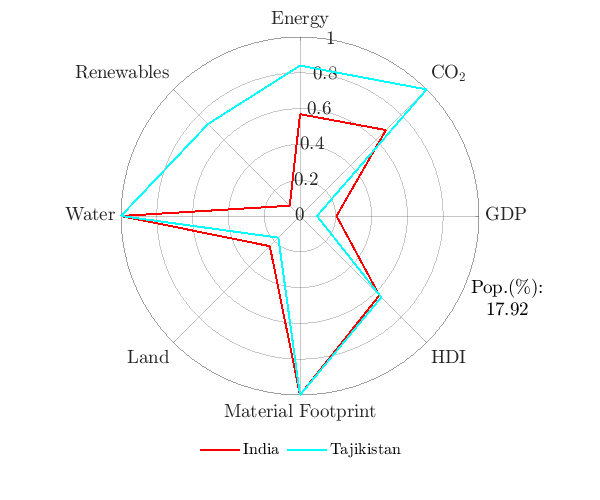

N=length(IN); 
C = hsv(N);
i=0;
figure()

for n=IN'
    i=i+1;
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

end

LegT=Labels(IN);
ax = gca;
axPos = ax.Position;
ax.Position = axPos+ [0 0.05 0 0];
legend(LegT,'Position',[0.45 0.05 0.1 0.1],'FontSize', 12,'NumColumns',3,...
    'box','off','interpreter','latex')
set(gcf,'Position',[0 0 600 500])
Pop_C=nansum(Pop(setdiff(IN,1)))/Pop(1)*100;
SP=sprintf('%.2f',Pop_C);
annotation('textbox', [0.845 0.45 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");

if P=='T'
    print('-depsc2','-r400','IN_15.eps')
end

## Egypt

EG=intersect(Wat_L,intersect(Mat_H,Land_L));
Labels(EG)

ans = 7×1 cell array
    {'Algeria'   }
    {'Djibouti'  }
    {'Egypt'     }
    {'Kenya'     }
    {'Mauritania'}
    {'Pakistan'  }
    {'Yemen'     }


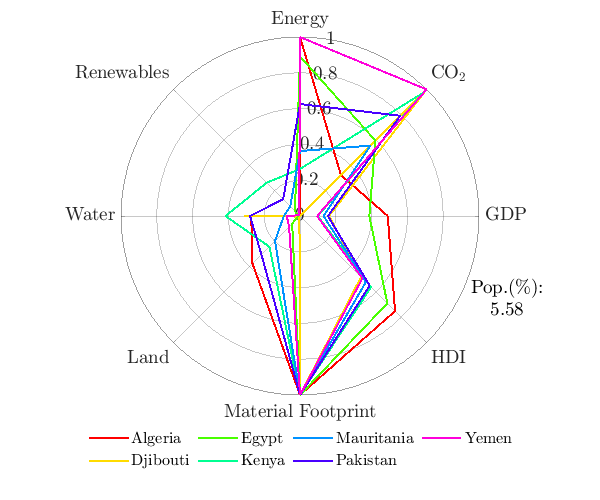

N=length(EG); 
C = hsv(N);
i=0;
figure()

for n=EG'
    i=i+1;
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

end

LegT=Labels(EG);
ax = gca;
axPos = ax.Position;
ax.Position = axPos+ [0 0.05 0 0];
legend(LegT,'Position',[0.45 0.05 0.1 0.1],'FontSize', 12,'NumColumns',4,...
    'box','off','interpreter','latex')
set(gcf,'Position',[0 0 600 500])
Pop_C=nansum(Pop(setdiff(EG,1)))/Pop(1)*100;
SP=sprintf('%.2f',Pop_C);
annotation('textbox', [0.845 0.45 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");

if P=='T'
    print('-depsc2','-r400','EG_15.eps')
end

## USA

US=intersect(Wat_H,intersect(GDP_H,intersect(En_H,Mat_L)))

US =      9
    24
    32
    45
   114
   158


Labels(US)

ans = 6×1 cell array
    {'Australia'    }
    {'Brunei'       }
    {'Canada'       }
    {'Denmark'      }
    {'Norway'       }
    {'United States'}


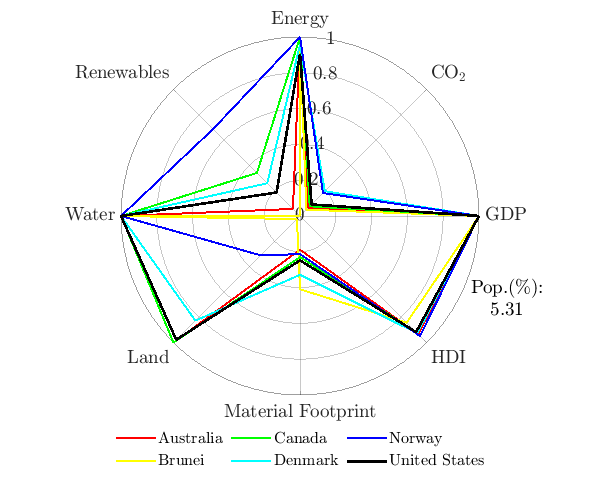

N=length(US); 
C = hsv(N);
i=0;
figure()

for n=US'
    i=i+1;
    if n==158
       Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color','k','linewidth',2)
    hold on 
    else
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
    end
end

LegT=Labels(US);
ax = gca;
axPos = ax.Position;
ax.Position = axPos+ [0 0.05 0 0];
legend(LegT,'Position',[0.45 0.05 0.1 0.1],'FontSize', 12,'NumColumns',3,...
    'box','off','interpreter','latex')
set(gcf,'Position',[0 0 600 500])
Pop_C=nansum(Pop(setdiff(US,1)))/Pop(1)*100;
SP=sprintf('%.2f',Pop_C);
annotation('textbox', [0.845 0.45 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");
if P=='T'
    print('-depsc2','-r400','US_15.eps')
end

## Brazil

BR=intersect(CO2_L,intersect(GDP_M,intersect(En_M,intersect(Mat_L,intersect(find(Land_cat(:,yo)~='L'),find(Ren_cat(:,yo)~='L'))))))

BR =     23
   125
   159


Labels(BR)

ans = 3×1 cell array
    {'Brazil' }
    {'Romania'}
    {'Uruguay'}


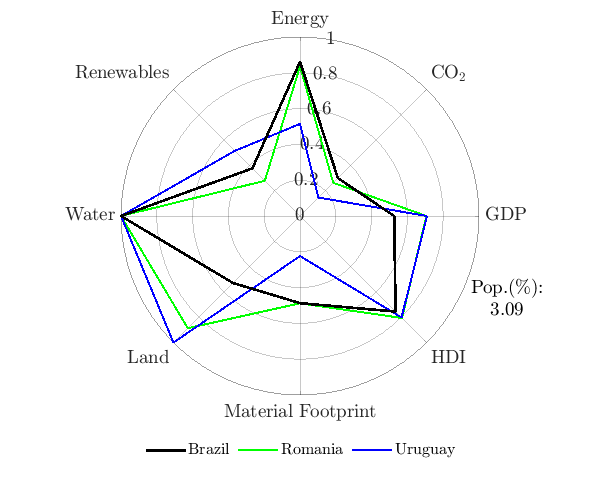

N=length(BR); 
C = hsv(N);
i=0;
figure()

for n=BR'
    i=i+1;
    if n==23
       Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color','k','linewidth',2)
    hold on 
    else
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
    end
end
 Values=Ind_S(23,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color','k','linewidth',2)
LegT=Labels(BR);
ax = gca;
axPos = ax.Position;
ax.Position = axPos+ [0 0.05 0 0];
legend(LegT,'Position',[0.45 0.05 0.1 0.1],'FontSize', 12,'NumColumns',3,...
    'box','off','interpreter','latex')
set(gcf,'Position',[0 0 600 500])
Pop_C=nansum(Pop(setdiff(BR,1)))/Pop(1)*100;
SP=sprintf('%.2f',Pop_C);
annotation('textbox', [0.845 0.45 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");
if P=='T'
    print('-depsc2','-r400','BR_15.eps')
end

## Indonesia

IND=intersect(Mat_H,intersect(CO2_M,intersect(En_H,Land_L)));
Labels(IND)

ans = 6×1 cell array
    {'Angola'   }
    {'Congo'    }
    {'Gabon'    }
    {'Ghana'    }
    {'Indonesia'}
    {'Nigeria'  }


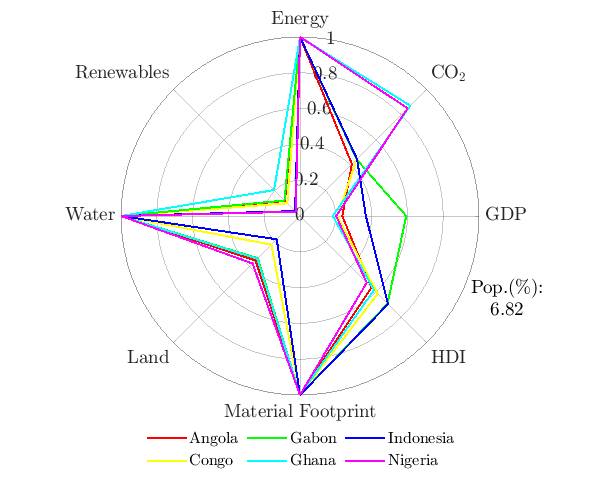

N=length(IND); 
C = hsv(N);
i=0;
figure()

for n=IND'
    i=i+1;
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

end

LegT=Labels(IND);
ax = gca;
axPos = ax.Position;
ax.Position = axPos+ [0 0.05 0 0];
legend(LegT,'Position',[0.45 0.05 0.1 0.1],'FontSize', 12,'NumColumns',3,...
    'box','off','interpreter','latex')
set(gcf,'Position',[0 0 600 500])
Pop_C=nansum(Pop(setdiff(IND,1)))/Pop(1)*100;
SP=sprintf('%.2f',Pop_C);
annotation('textbox', [0.845 0.45 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");

if P=='T'
    print('-depsc2','-r400','IND_15.eps')
end

## Mexico

ME=intersect(Mat_M,intersect(CO2_L,intersect(En_H,intersect(Wat_H,Land_L))))

ME =      1
    73
   101
   103
   141


Labels(ME)

ans = 5×1 cell array
    {'World'   }
    {'Iran'    }
    {'Mexico'  }
    {'Mongolia'}
    {'Suriname'}


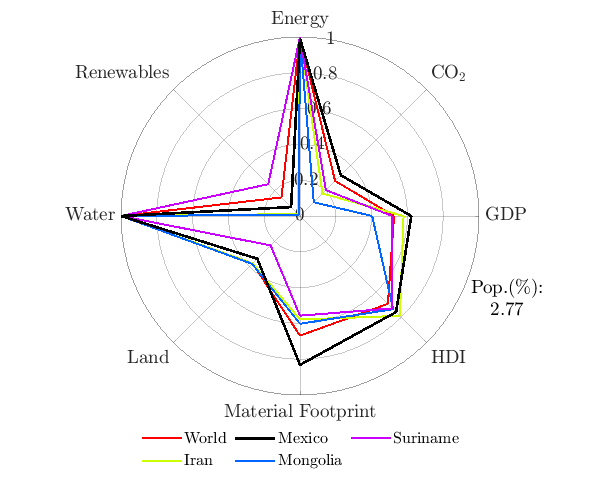

N=length(ME); 
C = hsv(N);
i=0;
figure()
for n=ME'
    i=i+1;
    if n==101
       Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color','k','linewidth',2)
    hold on 
    else
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
    end
end

       Values=Ind_S(101,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color','k','linewidth',2)
   

LegT=Labels(ME);
ax = gca;
axPos = ax.Position;
ax.Position = axPos+ [0 0.05 0 0];

legend(LegT,'Position',[0.45 0.05 0.1 0.1],'FontSize', 12,'NumColumns',3,...
    'box','off','interpreter','latex')
set(gcf,'Position',[0 0 600 500])
Pop_C=nansum(Pop(setdiff(ME,1)))/Pop(1)*100;
SP=sprintf('%.2f',Pop_C);
annotation('textbox', [0.845 0.45 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");
if P=='T'
    print('-depsc2','-r400','ME_15.eps')
end

## Japan

JP=intersect(En_L,intersect(HDI_H,intersect(GDP_H,intersect(Wat_H,Land_L))))

JP =     10
    16
    61
    75
    77
    79
    92
   135
   137


Labels(JP)

ans = 9×1 cell array
    {'Austria'    }
    {'Belgium'    }
    {'Germany'    }
    {'Ireland'    }
    {'Italy'      }
    {'Japan'      }
    {'Luxembourg' }
    {'Slovenia'   }
    {'South Korea'}


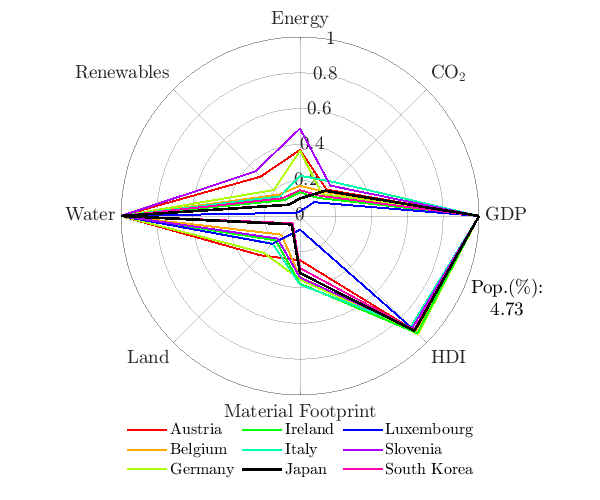

N=length(JP); 
C = hsv(N);
i=0;
figure()

for n=JP'
    i=i+1;
    if n==79
       Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color','k','linewidth',2)
    hold on 
    else
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
    end
end

    Values=Ind_S(79,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color','k','linewidth',2)
   
   

LegT=Labels(JP);
ax = gca;
axPos = ax.Position;
ax.Position = axPos+ [0 0.05 0 0];
legend(LegT,'Position',[0.45 0.05 0.1 0.1],'FontSize', 12,'NumColumns',3,...
    'box','off','interpreter','latex')
set(gcf,'Position',[0 0 600 500])
Pop_C=nansum(Pop(setdiff(JP,1)))/Pop(1)*100;
SP=sprintf('%.2f',Pop_C);
annotation('textbox', [0.845 0.45 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");

if P=='T'
    print('-depsc2','-r400','JP_15.eps')
end

## Saudi Arabia

SA=intersect(En_H,intersect(HDI_H,intersect(GDP_H,intersect(Wat_L,Land_L))))

SA =     12
    83
   115
   124
   129
   156


Labels(SA)

ans = 6×1 cell array
    {'Bahrain'             }
    {'Kuwait'              }
    {'Oman'                }
    {'Qatar'               }
    {'Saudi Arabia'        }
    {'United Arab Emirates'}


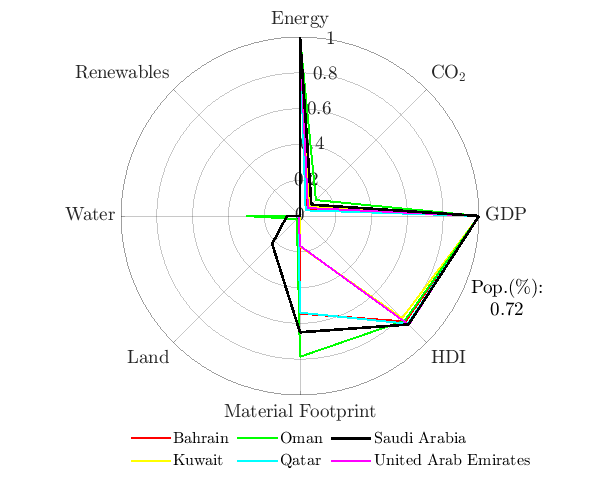

N=length(SA); 
C = hsv(N);
i=0;
figure()

for n=SA'
    i=i+1;
    if n==129
       Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color','k','linewidth',2)
    hold on 
    else
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
    end
end

    Values=Ind_S(129,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color','k','linewidth',2)
    hold on 
  

LegT=Labels(SA);
ax = gca;
axPos = ax.Position;
ax.Position = axPos+ [0 0.05 0 0];
legend(LegT,'Position',[0.5 0.05 0.1 0.1],'FontSize', 12,'NumColumns',3,...
    'box','off','interpreter','latex')
set(gcf,'Position',[0 0 600 500])
Pop_C=nansum(Pop(setdiff(SA,1)))/Pop(1)*100;
SP=sprintf('%.2f',Pop_C);
annotation('textbox', [0.845 0.45 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");

if P=='T'
    print('-depsc2','-r400','KS_15.eps')
end

## Argetina

AR=intersect(find(Exp_cat(:,yo)~='L'),intersect(Wat_H,intersect(Land_H,intersect(Ren_L,find(Mat_cat(:,yo)~='L')))));
AR=intersect(find(GDP_cat(:,yo)~='L'),intersect(find(Exp_cat(:,yo)~='L'),intersect(Wat_H,intersect(Land_H,find(Ren_cat(:,yo)~='H')))));
Labels(AR)

ans = 5×1 cell array
    {'Argentina' }
    {'Australia' }
    {'Canada'    }
    {'Kazakhstan'}
    {'Russia'    }


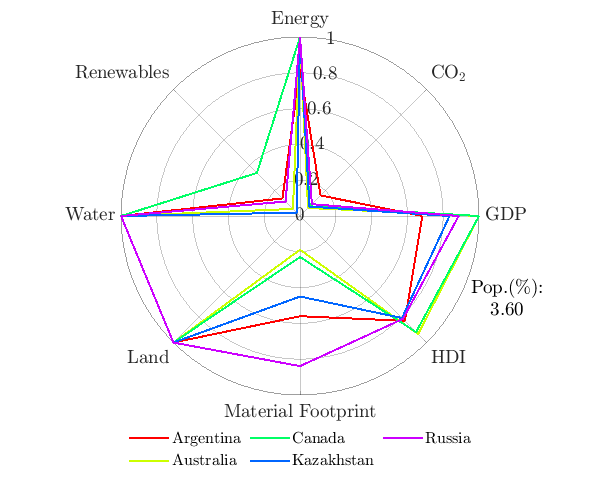

N=length(AR); 
C = hsv(N);
i=0;
figure()

for n=AR'
    i=i+1;
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

end

LegT=Labels(AR);
ax = gca;
axPos = ax.Position;
ax.Position = axPos+ [0 0.05 0 0];
legend(LegT,'Position',[0.45 0.05 0.1 0.1],'FontSize', 12,'NumColumns',3,...
    'box','off','interpreter','latex')
set(gcf,'Position',[0 0 600 500])
Pop_C=nansum(Pop(setdiff(AR,1)))/Pop(1)*100;
SP=sprintf('%.2f',Pop_C);
annotation('textbox', [0.845 0.45 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");

if P=='T'
    print('-depsc2','-r400','AR_15.eps')
end

## Bangladesh

BA=intersect(find(CO2_cat(:,yo)~='L'),intersect(Land_L,intersect(find(Exp_cat(:,yo)~='L'),intersect(find(Water_cat(:,yo)~='L'),intersect(Ren_L,GDP_L)))));
Labels(BA)

ans = 9×1 cell array
    {'Angola'    }
    {'Bangladesh'}
    {'Congo'     }
    {'Ecuador'   }
    {'Ghana'     }
    {'India'     }
    {'Indonesia' }
    {'Nigeria'   }
    {'Vietnam'   }


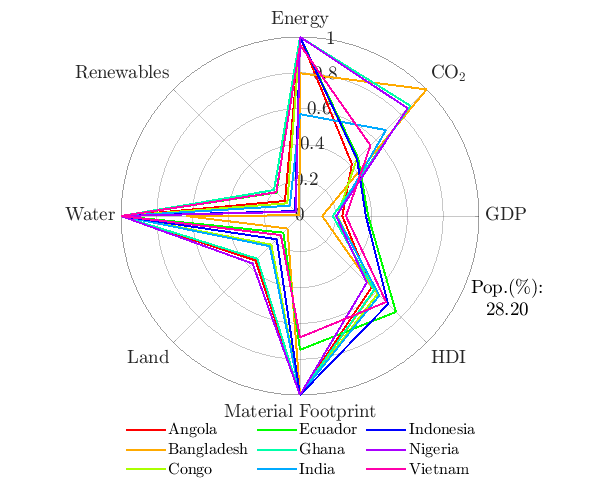

N=length(BA); 
C = hsv(N);
i=0;
figure()

for n=BA'
    i=i+1;
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

end

LegT=Labels(BA);
ax = gca;
axPos = ax.Position;
ax.Position = axPos+ [0 0.05 0 0];
legend(LegT,'Position',[0.45 0.05 0.1 0.1],'FontSize', 12,'NumColumns',3,...
    'box','off','interpreter','latex')
set(gcf,'Position',[0 0 600 500])
Pop_C=nansum(Pop(setdiff(BA,1)))/Pop(1)*100;
SP=sprintf('%.2f',Pop_C);
annotation('textbox', [0.845 0.45 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");

if P=='T'
    print('-depsc2','-r400','BA_15.eps')
end